### Section 5

% a)

% 0.0001201z^8 + 0.0009608z^7 + 0.003363z^6 + 0.006725z^5 + 0.008407z^4 + 0.006725z^3 + 0.003363z^2 + 0.0009608z + 0.0001201
% --------------------------------------------------------------------------------------------------------------
% z^8 - 3.919z^7 + 7.325z^6 - 8.275z^5 + 6.106z^4 - 2.989z^3 + 0.9423z^2 - 0.1742z + 0.01442
% 
% num = [0.0001201 + 0.0009608 + 0.003363 + 0.006725 + 0.008407 + 0.006725 + 0.003363 + 0.0009608 + 0.0001201];
% denom = [ 1 + 3.919 + 7.325 - 8.275 + 6.106 - 2.989 + 0.9423 - 0.1742 + 0.01442];

% fvtool(0.0001201, 0.0009608, 0.003363, 0.006725, 0.008407, 0.006725, 0.003363, 0.0009608, 0.0001201, 1, 3.919, 7.325, -8.275,  6.1064, -2.989, 0.9423, -0.1742, 0.01442)


num = [0.0001201, 0.0009608, 0.003363, 0.006725, 0.008407, 0.006725, 0.003363, 0.0009608, 0.0001201];
denom = [1, -3.919, 7.325, -8.275, 6.106, -2.989, 0.9423, -0.1742, 0.01442];

% fvtool(num, denom);

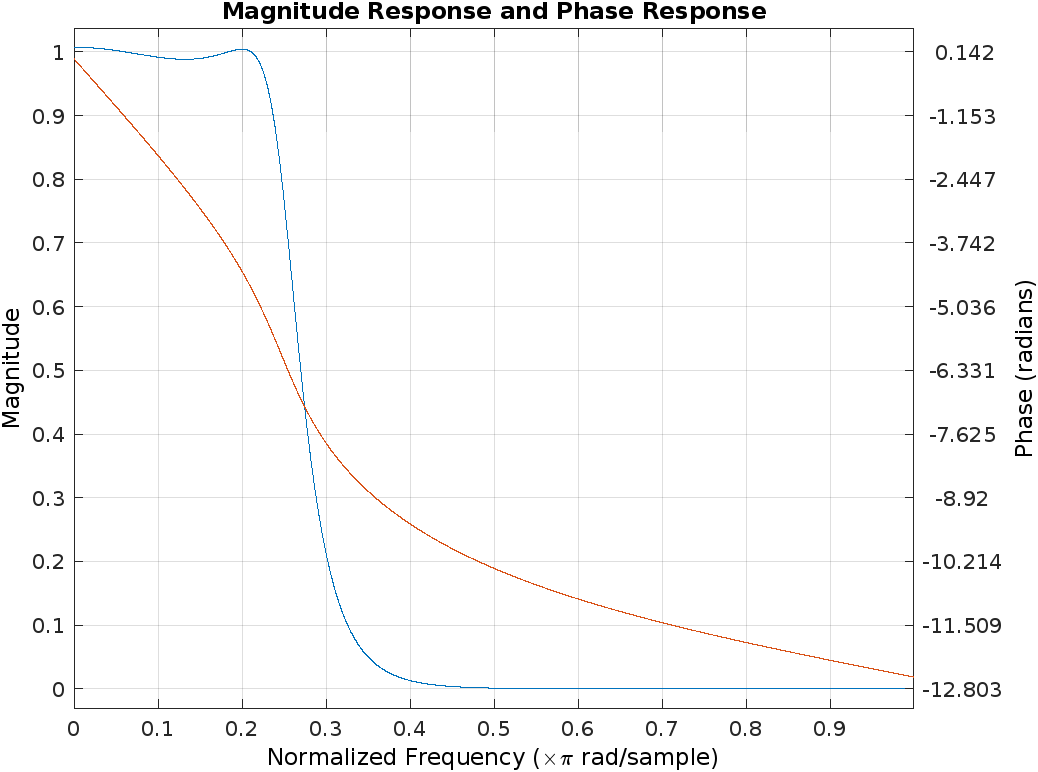

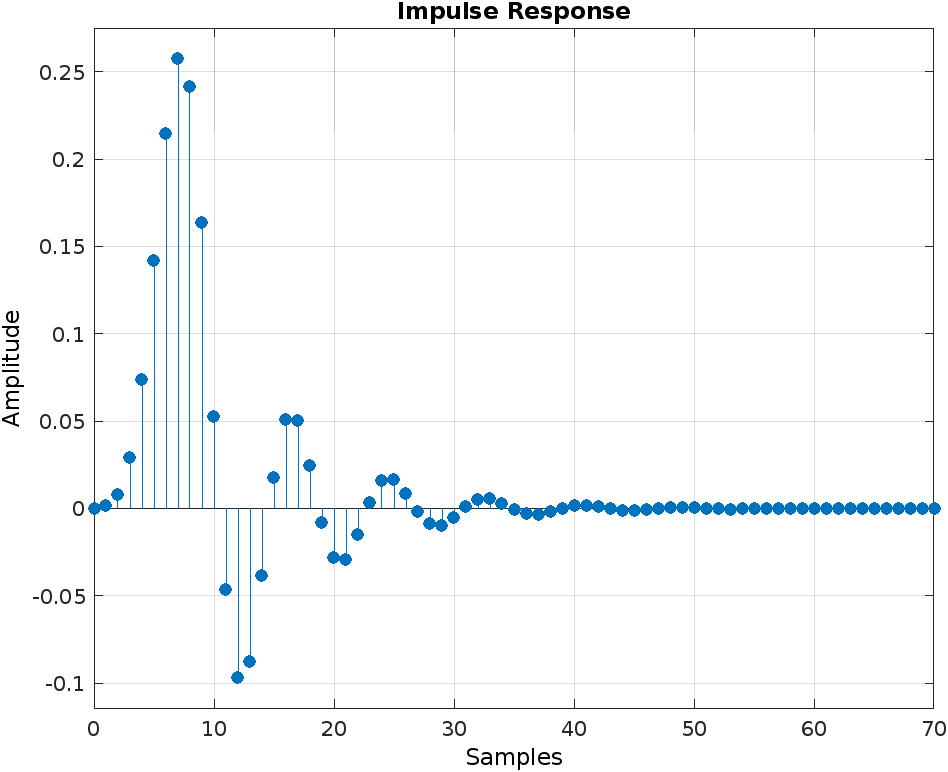

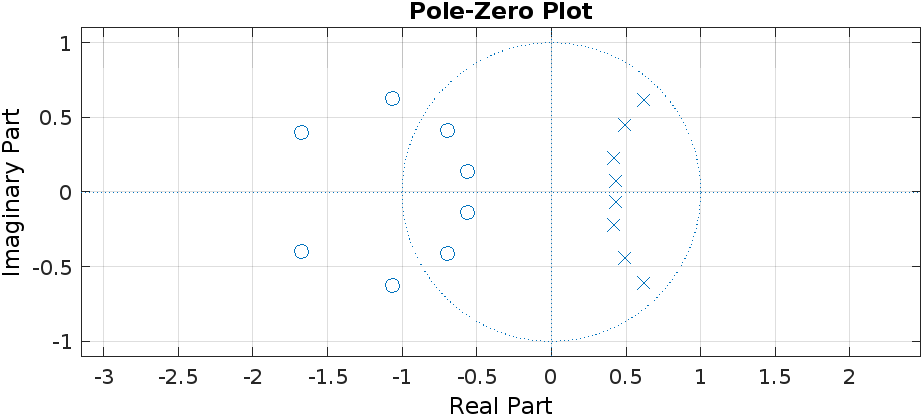

#### Section 5 | part b)

#### i) Is this filter IIR or FIR?

        This is a IIR Filter.

**iI) Is this filter Lowpass, Highpass, or Bandstop?**

        This is a low-pass filter.

#### iii) What is the approximate cutoff frequency of the filter?

        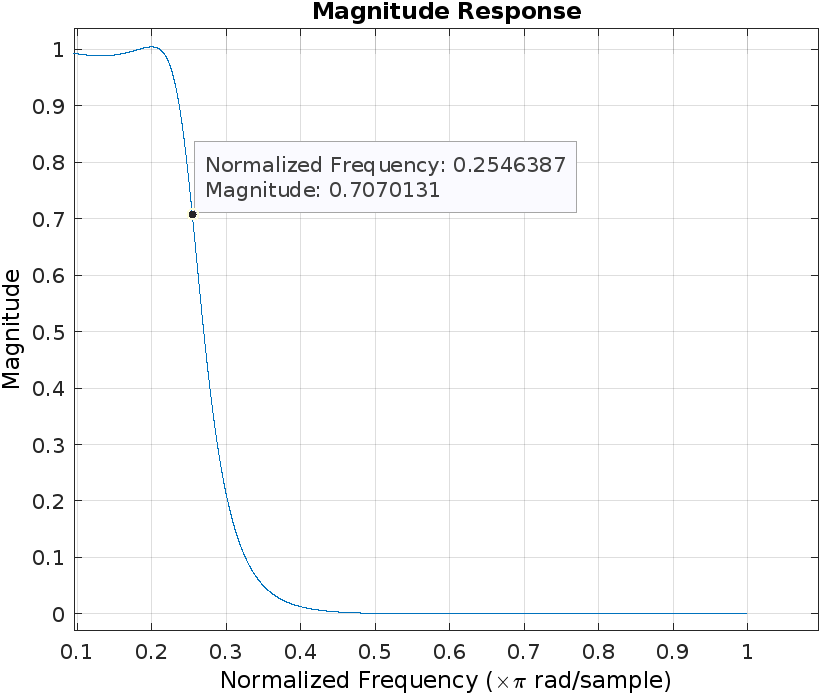

    Normalized Cutoff Frequency = 0.25464 $\left(\;\frac{1}{\pi \;}\right.$ rad/sample)

    Cutoff Frequency = ( 0.25464) * ($\pi$) $\approx \;$0.8 rad/sample

#### Section 5 | part c)

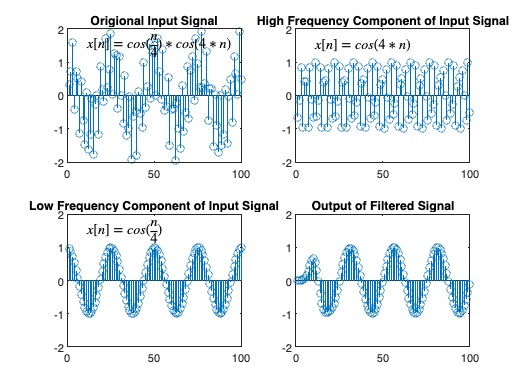

n = 1:1:100;
y = cos(4*n) + cos(n/4);
y_high = cos(4*n);
y_low = cos(n/4);

y_filtered = filter(num, denom, y);

figure1 = figure();

subplot(2,2,1);
stem(y);
ylim([-2, 2]);
title("Origional Input Signal");
text(10, 1.5, "$$x[n]=cos(\frac{n}{4})*cos(4*n)$$", Interpreter="latex");

subplot(2,2,2);
stem(y_high);
ylim([-2, 2]);
title("High Frequency Component of Input Signal");
text(10, 1.5, "$$x[n]=cos(4*n)$$", Interpreter="latex");

subplot(2,2,3);
stem(y_low);
ylim([-2, 2]);
title("Low Frequency Component of Input Signal");
text(10, 1.5, "$$x[n]=cos(\frac{n}{4})$$", Interpreter="latex");

subplot(2,2,4);
stem(y_filtered);
ylim([-2, 2]);
title("Output of Filtered Signal");